load('workspace.mat')
Xtest_RAW = Xtest; % task evaluation set
Xtrain_RAW = Xtrain; % task evaluation set
TR_RAW = [ytrain Xtrain(:,2:end)]; %Training set
TR_RAW.id; %Column 1
TR_RAW.y; %Column 2 

% Rows Pairwise allows to ignore missing values
% Spearman: WORKS FOR ANY MONOTONIC
cc = corr(TR_RAW{:,2:end}, "Type","Spearman","Rows","pairwise");
% Pearson: WORKS FOR LINEAR ONLY
%cc_p = corr(TS.Variables, "Type","Pearson", "Rows","pairwise");


% correlations of features to label
cc_y = cc(1,2:end);
[cc_y_sorted, cc_order] = sort(abs(cc_y),'descend');

% most features have sub .1 correlation 
plot(cc_y_sorted)

% move NaNs to end
cc_order = [cc_order(~isnan(cc_y_sorted)) cc_order(isnan(cc_y_sorted))];

% sorted feature names 
%(+2 bc we had taken out id and y so there is offset)
feat_names_by_cc = TR_RAW.Properties.VariableNames(cc_order+2);
TR = TR_RAW(:,['id' 'y' feat_names_by_cc]);
Xtest = Xtest_RAW(:,['id' feat_names_by_cc]);
Xtrain = Xtrain_RAW(:,['id' feat_names_by_cc]);

% sort so I can see some clustering on a heatmap
n_hm_feats = 230;
cc_sorted = cc(:,[1,cc_order+1]);
cc_sorted = cc_sorted([1,cc_order+1],:);
heatmap(abs(cc_sorted(1:n_hm_feats,1:n_hm_feats)));

% maybe compare heatmap w/ feature only heatmap from test set

% remove outliers
TR_NOL = removeOutOfRange(TR, Xtest,0.08);

% remove only redected Outliers
TR_NOL = TR(~OLs,:);
shape_reduction = size(TR.Variables)- size(TR_NOL.Variables)

shape_reduction =     24     0


% look at corr after outlier removal
cc_nol = corr(TR_NOL{:,2:end}, "Type","Spearman","Rows","pairwise");

cc_y_nol = cc_nol(1,2:end);

% sort these, but they didn't actually get scrambled that much
[cc_y_nol_sorted, cc_nol_order] = sort(abs(cc_y_nol),'descend');
cc_nol_order=[cc_nol_order(~isnan(cc_y_nol_sorted)) cc_nol_order(isnan(cc_y_nol_sorted))];
cc_nol_order = cc_nol_order + 1; %we had y in there before
plot(cc_y_nol_sorted);

% compare cc ordering before and after outlier removal
scatter(cc_y_sorted,abs(cc_y_nol));
scatter(1:length(cc_nol_order), cc_nol_order);

% sort so I can see some clustering on a heatmap NOL
n_hm_feats = 230;
cc_nol_sorted = cc_nol(:,[1,cc_nol_order]);
cc_nol_sorted = cc_nol_sorted([1,cc_nol_order],:);
heatmap(abs(cc_nol_sorted(1:n_hm_feats,1:n_hm_feats)));

% lets take a look at the test set data 
cc_t = corr(Xtest{:,2:end}.Variables, "Type","Spearman","Rows","pairwise");

% can I see some clustering on a test set corr heatmap?
% not sorting bc I don't know labels
n_hm_feats = 230;
heatmap(abs(cc_t(1:n_hm_feats,1:n_hm_feats)));

% fill missing the stupid way (median imputation) with OL
TR_MI = TR;
nans_b4 = sum(sum(isnan(TR.Variables))); nans_b4

nans_b4 = 76929

A = TR_MI.Variables;
medians = nanmedian(A);
to_replace = isnan(A).*medians;
A(isnan(A)) = to_replace(isnan(A));
TR_MI.Variables = A;
nans_left = sum(sum(isnan(TR_MI.Variables))); nans_left

nans_left = 0

% we get really crappy peak in distrib at median

% fill missing the stupid way (median imputation) without OL
nans_b4 = sum(sum(isnan(TR_NOL.Variables))); nans_b4

nans_b4 = 75407

TR_CLEAN = TR_NOL;
TE_CLEAN = Xtest;
[n_train, ~] = size(TR_NOL.Variables);
%[n_test, ~] = size(Xtest.Variables);
A = [TR_NOL{:,3:end}; Xtest{:,2:end}];
medians = nanmedian(A);
to_replace = isnan(A).*medians;
A(isnan(A)) = to_replace(isnan(A));
TR_CLEAN.Variables = [TR_NOL{:,1:2} A(1:n_train,:)];
TE_CLEAN.Variables = [Xtest{:,1} A(n_train+1:end,:)];
nans_left = sum(sum(isnan(A))); nans_left

nans_left = 0

% we still get really crappy peak in distrib at median

% feature pre-selection, remember we sorted by correlation to y
nsel = 228

nsel = 228

TR_SEL = TR_CLEAN(:,1:nsel+2); 
TE_SEL = TE_CLEAN(:,1:nsel+1);

% fit with lasso...
X = TR_SEL{:,3:end};
y = TR_SEL.y;
[b, fitinfo] = lasso(X,y,'CV',10);

% bestlambda
best_lambda_index = fitinfo.IndexMinMSE;
coef = b(:,best_lambda_index);
coef0 = fitinfo.Intercept(best_lambda_index);

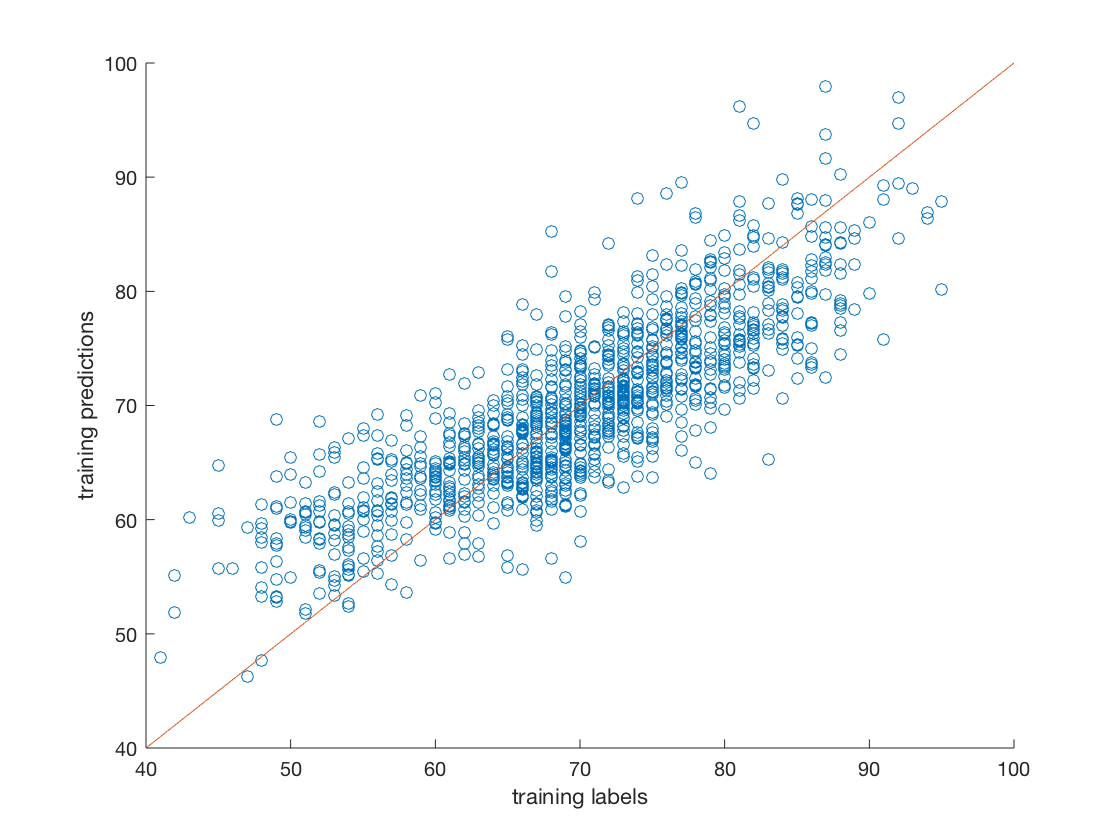

% Check it out ON TRAINING SAMPLES  
yhat = X*coef + coef0;
clf
scatter(TR_SEL.y, yhat);
hold on
plot([40; 100],[40; 100])
hold off
xlabel('training labels')
ylabel('training predictions')


train_r2 = r2_score(TR_SEL.y, yhat)

train_r2 = 0.6837

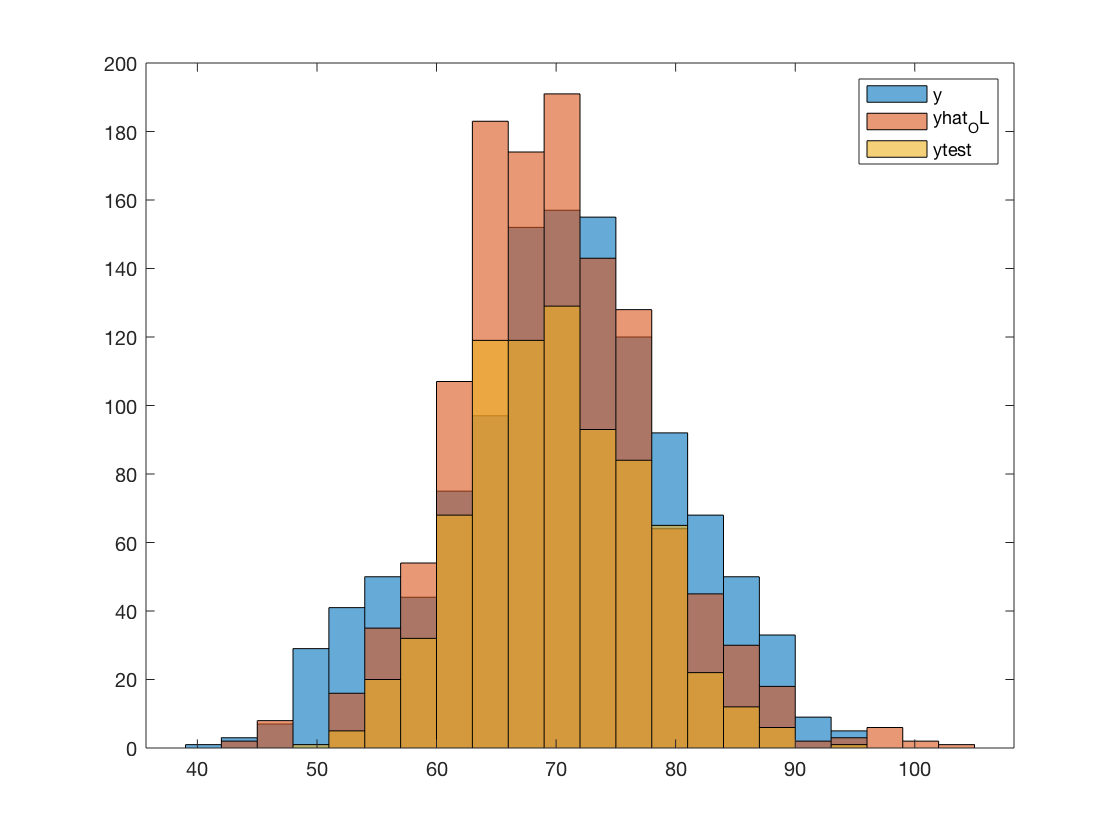

% on test data
X_test = TE_SEL{:,2:end};
ytest = X_test*coef + coef0;
histogram(y)
hold on
histogram(yhat_OL)
histogram(ytest)

legend
hold off

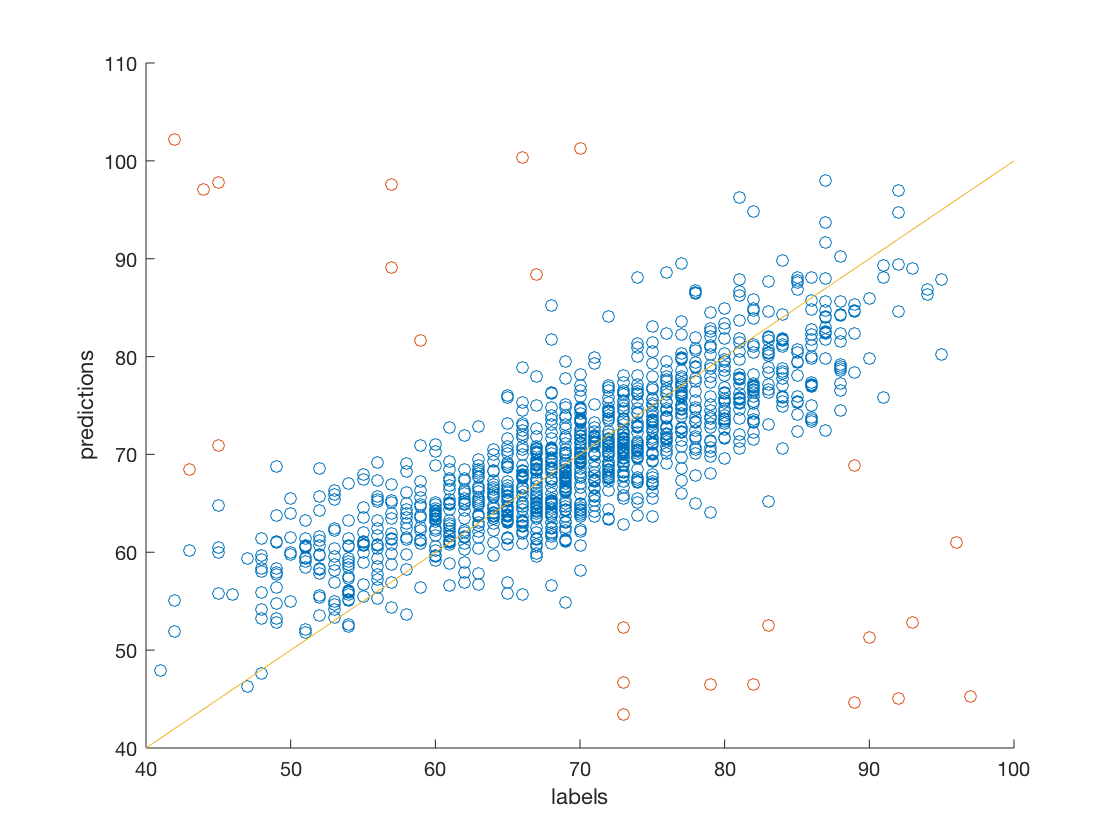

% Check it out ON OUTLIERS  
TR_OL = TR_MI(:,1:230);
XO = TR_OL{:,3:end};

yhat_OL = XO*coef + coef0;
OLs = abs(TR_OL.y - yhat_OL) > 20;

scatter(TR_OL.y,yhat_OL);
hold on
scatter(TR_OL.y(OLs),yhat_OL(OLs));
plot([40; 100],[40; 100])
hold off


xlabel('labels')
ylabel('predictions')

train_r2_with_OL = r2_score(TR_MI.y, yhat_OL)

train_r2_with_OL = 0.4308

OL_ids = TR_OL{OLs,1};


% validate outlier removal by training with outliers included

% feature selection, remember we sorted by correlation to y
TR_OL = TR_MI(:,1:230);
XO = TR_OL{:,3:end};
yO = TR_OL.y;
[b_OL, fitinfo_OL] = lasso(XO,yO,'CV',10);

 % bestlambda
best_lambda_index_OL = fitinfo_OL.IndexMinMSE;
coef_OL = b_OL(:,best_lambda_index_OL);
coef0_OL = fitinfo.Intercept(best_lambda_index_OL);

yhat_OL_OL = XO*coef_OL + coef0_OL;

scatter(TR_OL.y,yhat_OL_OL);
hold on
plot([40; 100],[40; 100])
hold off
xlabel('training labels')
ylabel('training predictions')
train_r2 = r2_score(TR_MI.y, yhat_OL_OL)


function r2 = r2_score(y, yhat)
    r2 = 1 - 1-(y - yhat).^2/sum((y - mean(y)).^2);
end

function cleanTR = removeOutOfRange(TR,TE,tol)
    %%remove outliers in the most stupid way I can think of

    % NaNs don't seem to be an issue for this
    % med = median(TE);
    % TENaNs = isnan(TE);
    % TRNaNs = isnan(TR);
    % for i=1:length(med)
    %     TE(TENaNs(:,i),i) = med(i);
    %     TR(TRNaNs(:,i),i) = med(i);
    % end
    
    lower = min(TE{:,2:end});
    upper = max(TE{:,2:end});
    
    disp("positives: "+ sum(lower>=0));
    disp("negatives: "+ sum(upper<=0));
    below = TR{:,3:end} < lower-abs(lower)*tol;
    above = TR{:,3:end} > upper+abs(upper)*tol;
    
    disp("violated_positives = "+sum(min(TR{:,3:end})<0 & lower>=0));
    disp("violated_negatives = "+sum(max(TR{:,3:end})>0 & upper<=0));

    
    outlier_indeces = above+below;
    n_outliers_by_feature = sum(outlier_indeces,1);
    n_outliers_by_sample = sum(outlier_indeces,2);

    histogram(n_outliers_by_feature, 100);
    disp("n_clean_features = " + sum(n_outliers_by_feature<1)+ "/" +(size(TR,2)-2));
    figure
    histogram(n_outliers_by_sample, 100);
    disp("n_clean_samples = " + sum(n_outliers_by_sample<1) + "/" +size(TR,1));
    disp("n_oops_samples = " + sum(n_outliers_by_sample==1) + "/" +size(TR,1));

    cleanTR = TR;
    cleanTR(n_outliers_by_sample>0,:) = [];

end